Model Switiching 

This script demonstrates the switiching process for the small traction changes. The Script utilizes the PosMul structure identified from the GPS fit script and utilizes it for estimation. The test data structure is the concatenated dataset composed of motion trajectories. 

Both the TestData and PosMul structures are provided in the github repo for recreating the results.


%
clc
clear
load('TestData.mat')
load('PosMul.mat')

%%% Initializations

K1 = PosMul(2).K ;
K2 = PosMul(4).K ;
K3 = PosMul(6).K ;
K4 = PosMul(8).K ;

M1 = PosMul(2).M ;
M2 = PosMul(4).M ;
M3 = PosMul(6).M ;
M4 = PosMul(8).M ;

idx = 8;

%x = data(idx).X ;
%y = data(idx).Y ;
%theta = data(idx).theta ;

x = [data(6).X(1:100),data(4).X(101:end)];
y = [data(6).Y(1:100),data(4).Y(101:end)];
theta = [data(6).theta(1:150)',data(4).theta(151:end)'];
u1_ = [data(6).u1(1:end)];
u2_ = [data(6).u2(1:end)];


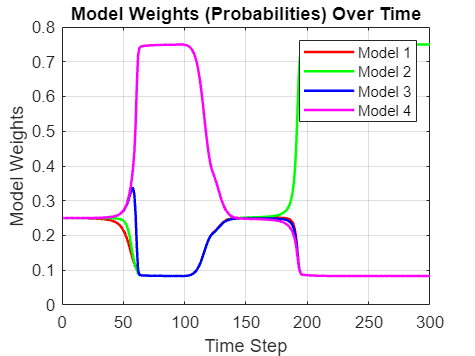

% IMM-EKF loop (including covariance mixing)
dt = 0.1;
num_steps = length(data(idx).u1);
x_est = zeros(3, num_steps);  % Estimated state [x; y; theta]
model_probs = zeros(4, num_steps);  % Store model probabilities

% Initial state and covariance for all models
x0 = [0; 0; 0];  % Initial state, modify if you have specific initial conditions
P0 = eye(3);  % Initial covariance for each model
Q = 0.3 * eye(3);  % Process noise covariance
R = 0.5 * eye(3);  % Measurement noise covariance

% Define transition matrix
trP = 0.75;
Pi = trP * eye(4) + (1 - trP) / 3 * (ones(4) - eye(4));

% Initialize state and covariance for each model
x1 = x0; P1 = P0;
x2 = x0; P2 = P0;
x3 = x0; P3 = P0;
x4 = x0; P4 = P0;

mu = [0.25, 0.25, 0.25, 0.25];  % Initial model probabilities

% Run IMM-EKF loop
for k = 1:num_steps
    % Extract control inputs
    u1=u1_(k);
    u2=u2_(k);
    
    % Step 1: Mixing step (state and covariance mixing)
    % Mix the states
    x1_mix = sum(Pi(1,:) .* mu .* [x1, x2, x3, x4], 2);
    x2_mix = sum(Pi(2,:) .* mu .* [x1, x2, x3, x4], 2);
    x3_mix = sum(Pi(3,:) .* mu .* [x1, x2, x3, x4], 2);
    x4_mix = sum(Pi(4,:) .* mu .* [x1, x2, x3, x4], 2);
    
    % Mix the covariances
    P1_mix = zeros(3);  % Initialize mixed covariance for Model 1
    P2_mix = zeros(3);  % Initialize mixed covariance for Model 2
    P3_mix = zeros(3);  % Initialize mixed covariance for Model 3
    P4_mix = zeros(3);  % Initialize mixed covariance for Model 4
    
    % Mix the covariances using the model probabilities (mu) and Markov transition matrix (Pi)
    for j = 1:4
        % Covariance mixing for Model 1
        x_diff_1 = eval(['x', num2str(j)]) - x1_mix;  % Difference between mixed state and individual state
        P1_mix = P1_mix + Pi(1,j) * mu(j) * (eval(['P', num2str(j)]) + x_diff_1 * x_diff_1');
    
        % Covariance mixing for Model 2
        x_diff_2 = eval(['x', num2str(j)]) - x2_mix;
        P2_mix = P2_mix + Pi(2,j) * mu(j) * (eval(['P', num2str(j)]) + x_diff_2 * x_diff_2');
    
        % Covariance mixing for Model 3
        x_diff_3 = eval(['x', num2str(j)]) - x3_mix;
        P3_mix = P3_mix + Pi(3,j) * mu(j) * (eval(['P', num2str(j)]) + x_diff_3 * x_diff_3');
        
        % Covariance mixing for Model 4
        x_diff_4 = eval(['x', num2str(j)]) - x4_mix;
        P4_mix = P4_mix + Pi(4,j) * mu(j) * (eval(['P', num2str(j)]) + x_diff_4 * x_diff_4');
    end
    
    % Step 2: Prediction step (for each model i = 1 to 4)
    [x1_pred, P1_pred] = ekf_predict(x1_mix, P1_mix, K1, M1, u1, u2, dt, Q);
    [x2_pred, P2_pred] = ekf_predict(x2_mix, P2_mix, K2, M2, u1, u2, dt, Q);
    [x3_pred, P3_pred] = ekf_predict(x3_mix, P3_mix, K3, M3, u1, u2, dt, Q);
    [x4_pred, P4_pred] = ekf_predict(x4_mix, P4_mix, K4, M4, u1, u2, dt, Q);
    
    % Update step with measurements
    [x1, P1, L1] = ekf_update(x1_pred, P1_pred, [x(k); y(k); theta(k)], R);
    [x2, P2, L2] = ekf_update(x2_pred, P2_pred, [x(k); y(k); theta(k)], R);
    [x3, P3, L3] = ekf_update(x3_pred, P3_pred, [x(k); y(k); theta(k)], R);
    [x4, P4, L4] = ekf_update(x4_pred, P4_pred, [x(k); y(k); theta(k)], R);
    
    % Update model probabilities
    mu1 = sum(Pi(:, 1) .* mu' .* [L1, L2, L3, L4]');
    mu2 = sum(Pi(:, 2) .* mu' .* [L1, L2, L3, L4]');
    mu3 = sum(Pi(:, 3) .* mu' .* [L1, L2, L3, L4]');
    mu4 = sum(Pi(:, 4) .* mu' .* [L1, L2, L3, L4]');
    
    % Normalize the probabilities
    mu_total = mu1 + mu2 + mu3 + mu4;
    mu = [mu1, mu2, mu3, mu4] ./ mu_total;

    % Combine estimates
    x_est(:, k) = mu(1) * x1 + mu(2) * x2 + mu(3) * x3 + mu(4) * x4;
    model_probs(:, k) = mu;
end


%% Plot Model Probabilities Over Time
figure;
plot(1:num_steps, model_probs(1, :), 'r', 'LineWidth', 1.5); hold on;
plot(1:num_steps, model_probs(2, :), 'g', 'LineWidth', 1.5);
plot(1:num_steps, model_probs(3, :), 'b', 'LineWidth', 1.5);
plot(1:num_steps, model_probs(4, :), 'm', 'LineWidth', 1.5);

title('Model Weights (Probabilities) Over Time');
xlabel('Time Step');
ylabel('Model Weights');
legend('Model 1', 'Model 2', 'Model 3', 'Model 4');
grid on;

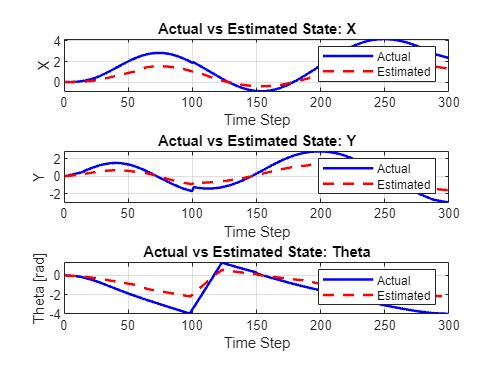


%% Plot Actual vs Estimated State Variables
figure;
subplot(3,1,1);
plot(1:num_steps, x, 'b', 'LineWidth', 1.5);  % Actual x
hold on;
plot(1:num_steps, x_est(1, :), 'r--', 'LineWidth', 1.5);  % Estimated x
title('Actual vs Estimated State: X');
xlabel('Time Step');
ylabel('X');
legend('Actual', 'Estimated');
grid on;

subplot(3,1,2);
plot(1:num_steps, y, 'b', 'LineWidth', 1.5);  % Actual y
hold on;
plot(1:num_steps, x_est(2, :), 'r--', 'LineWidth', 1.5);  % Estimated y
title('Actual vs Estimated State: Y');
xlabel('Time Step');
ylabel('Y');
legend('Actual', 'Estimated');
grid on;

subplot(3,1,3);
plot(1:num_steps, theta, 'b', 'LineWidth', 1.5);  % Actual theta
hold on;
plot(1:num_steps, x_est(3, :), 'r--', 'LineWidth', 1.5);  % Estimated theta
title('Actual vs Estimated State: Theta');
xlabel('Time Step');
ylabel('Theta [rad]');
legend('Actual', 'Estimated');
grid on;